# **Bonus**

#### 所谓“机器学习”就是让机器从数据中，通过不断的积累和计算，学会与人类相近的技能。例如分辨不同种类的外星人。

#### 在遥远的M78星云有两种外星人--“正能量”外星人和“负能量”外星人。由于受到光照不同，对于“正能量”外星人，他们3倍的身高加上5倍的体重大于200；而对于“负能量”外星人，他们3倍的身高加上5倍的体重小于200。这条宇宙的“真实标准线”可写成如下两种形式： 

`3*身高 + 5*体重 - 200 = 0`

`体重 = -3/5*身高 + 40`

#### 如下图所示，红色的线表示区分“正/负能量”外星人的“标准线”（上述的公式）。红线上方的粉色点代表“正能量”外星人，红线下方的绿色点代表“负能量”外星人。

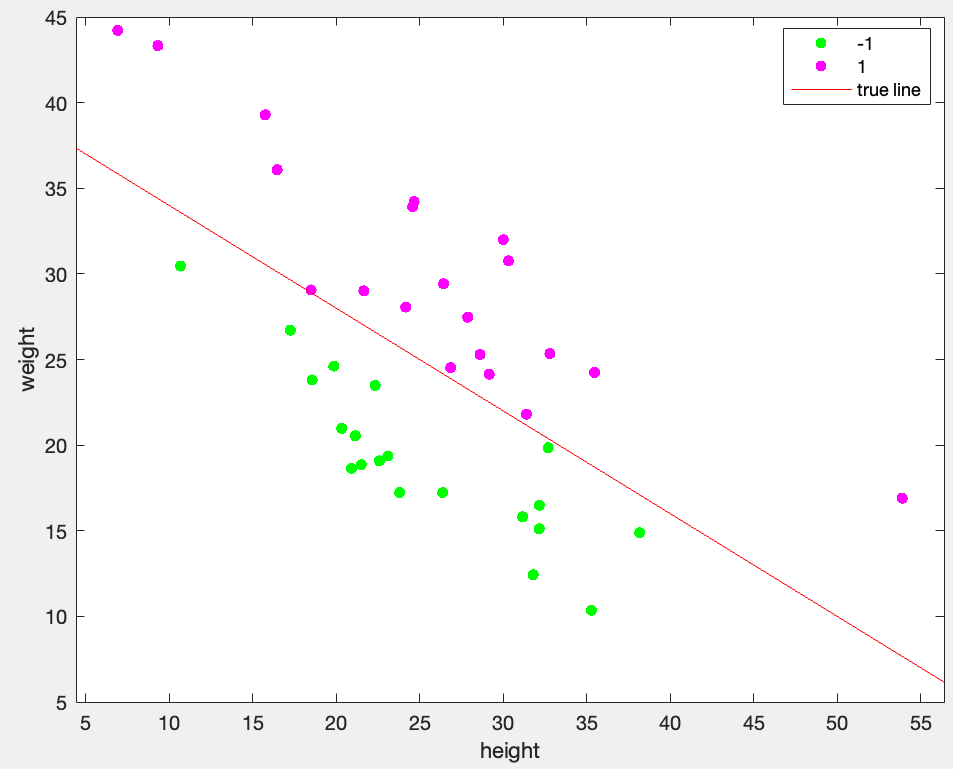

#### “机器”的目标是学习到一条与这条红线足够相似的线来作为“机器”判断外星人种类的标准。

#### 想让“机器”学习到这项技能，离不开充足的数据量进行训练。下面就让我们模拟出“正/负能量”外星人的数据，丢给“机器”让它学习。

#### 首先，我们确定样本的大小为 40：

clear
% 请补全代码
sample_size = 40;

#### 将样本平均分为两组，每组的样本量为 总样本大小的一半：

% 请补全代码
group_size = sample_size / 2;

#### 方便起见，我们固定一个随机数生成的种子，让每次随机的结果一样：

rng(2024)

#### 接下来，我们先生成外星人的身高数据。无论“正/负能量”外星人他们的身高都服从均值为25，标准差为8的正态分布。

#### 因此，我们需要生成一个大小为 1*40 正态分布 均值为25 标准差为8 的数组：

% 请补全代码
height = randn(1,40) * 8 + 25

height =    27.8792   31.3945   16.4684    6.9264    9.3295   21.6600   32.7992   30.3218   24.1676   24.5786   18.5026   35.4660   26.4314   53.8944   28.6144   26.8573   24.6677   15.7566   29.1620   30.0072   19.8603   10.6870   35.2832   20.9203   21.1538   32.6898   32.1576   26.3766   21.5056   22.3343   18.5639   31.8003   17.2573   23.1039   32.1730   20.3438   38.1744   31.1656   23.8030   22.5905


#### 我们假定身高数据的前20项为“正能量”外星人，记为 1；后20项为“负能量”外星人，记为 -1。

#### 因此，我们使用 repelem() 函数生成前20项为 1，后20项为 -1 的数组：

% 请补全代码
group = repelem([1,-1],20);

#### 之后，我们生成“正/负能量”外星人的体重数据。“正能量”外星人的体重在临界值上方 (0,10) 的区间内均匀浮动；“负能量”外星人的体重在临界值下方 (0,10) 的区间内均匀浮动。

#### 因此，我们分别构造两个 1*20 的数组。其中一个数组在上述等式临界值处加上1个在 (0,10) 之间均匀浮动的误差；另一组在上述等式临界值处减去1个在 (0,10) 之间均匀浮动的误差：

% 请补全代码
weight_pos = -3/5 * height(1:20) + 40 + randi([0,10],1,20)

weight_pos =    27.2725   21.1633   36.1190   44.8441   43.4023   29.0040   25.3205   30.8069   27.4994   34.2529   28.8984   24.7204   29.1411   17.6634   24.8314   23.8856   34.1994   39.5460   23.5028   31.9957


weight_neg = -3/5 * height(21:40) + 40 - randi([0,10],1,20)

weight_neg =    25.0838   30.5878    9.8301   18.4478   20.3077   20.3861   14.7054   17.1740   18.0966   23.5994   23.8616   11.9198   26.6456   19.1376   16.6962   20.7937   15.0954   15.3006   16.7182   18.4457


#### 将两组体重合并成1个 1*40 的体重数据：

% 请补全代码
weight = [weight_pos, weight_neg]

weight =    27.2725   21.1633   36.1190   44.8441   43.4023   29.0040   25.3205   30.8069   27.4994   34.2529   28.8984   24.7204   29.1411   17.6634   24.8314   23.8856   34.1994   39.5460   23.5028   31.9957   25.0838   30.5878    9.8301   18.4478   20.3077   20.3861   14.7054   17.1740   18.0966   23.5994   23.8616   11.9198   26.6456   19.1376   16.6962   20.7937   15.0954   15.3006   16.7182   18.4457


#### 我们可以将 身高，体重，组别 信息保存进一个 40*3 的矩阵中，如有需要可以保存至本地：

% 请补全代码
data = [height; weight; group]

data =    27.8792   31.3945   16.4684    6.9264    9.3295   21.6600   32.7992   30.3218   24.1676   24.5786   18.5026   35.4660   26.4314   53.8944   28.6144   26.8573   24.6677   15.7566   29.1620   30.0072   19.8603   10.6870   35.2832   20.9203   21.1538   32.6898   32.1576   26.3766   21.5056   22.3343   18.5639   31.8003   17.2573   23.1039   32.1730   20.3438   38.1744   31.1656   23.8030   22.5905
   27.2725   21.1633   36.1190   44.8441   43.4023   29.0040   25.3205   30.8069   27.4994   34.2529   28.8984   24.7204   29.1411   17.6634   24.8314   23.8856   34.1994   39.5460   23.5028   31.9957   25.0838   30.5878    9.8301   18.4478   20.3077   20.3861   14.7054   17.1740   18.0966   23.5994   23.8616   11.9198   26.6456   19.1376   16.6962   20.7937   15.0954   15.3006   16.7182   18.4457
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000 

### 恭喜你！以上我们就完成了模拟数据的创建，以下是机器学习算法相关的代码，如有兴趣可以自行研究。现在请开始运行程序，看看“机器”学习到的判断标准 (蓝色线条) 吧！

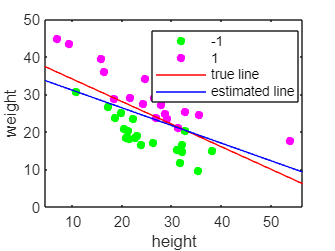

%% 作图
gscatter(height,weight,group,'gm');
true_x = [0,60];
true_y = -3/5*true_x + 40;
line(true_x,true_y,'Color','red','DisplayName','true line')

%% 机器学习算法的构建

% 初始化 身高、体重、常数项 的权重
w = repelem(0,3);

% 为while循环设置一个key
iscorrect = 0;

% 更新次数初始化为0
iteration = 0;

% 算法循环(如有能力可完成以下循环的全部内容)
while iscorrect == 0
    for i = 1:sample_size
        x = height(i);
        y = weight(i);
        input = [x,y,1]';

        %### 输出等于: 首先计算 权重w * 输入的值。之后若结果大于0输出为1；结果小于0输出为-1；等于0输出为0
        % 可以使用 sign() 函数
        output = sign(w*input);

        if output ~= group(i)
            % 有分类错误的样本，对权重更新
            w = w + group(i)*input';

            %### 每次发现分类错误，更新权重后，更新次数+1
            iteration = iteration + 1;

            break
        end

        if i == sample_size
            iscorrect = 1;
        end
    end
end

%% 作图
intercept = -w(3)/w(2);
slope = - w(1)/w(2);
estimated_y = slope*true_x + intercept;
line(true_x,estimated_y,'Color','blue','DisplayName','estimated line')